# Sampling and Aliasing

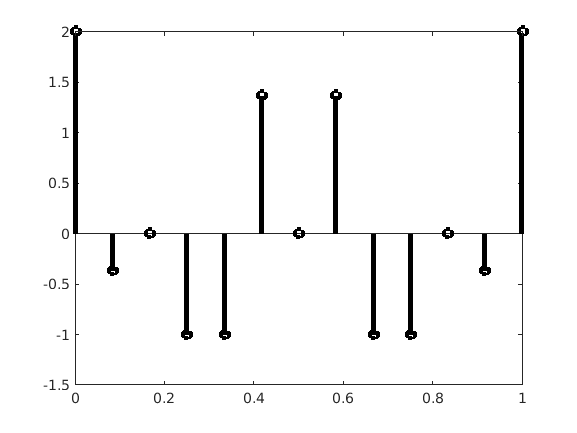

f1 = 2;
f2 = 5;
Fs = 12;
Ts = 1/Fs;
nT = [0:Ts:1];
xn = cos(2*pi*f1*nT) + cos(2*pi*f2*nT); %simple signal
figure(1)
stem(nT,xn,'k','LineWidth',3);

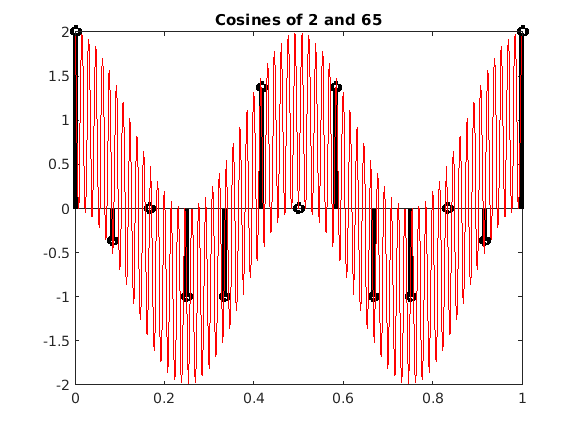

t = [0:0.001:1]; %fine time vector
f3 = [5 7 17 19 29 31 41 43 53 55 65];
for i=1:length(f3)
    clf
    stem(nT,xn,'k','LineWidth',3);
    axis([0,1,-2,2]);
    hold on;
    xa = cos(2*pi*f1*t)+cos(2*pi*f3(i)*t); %aliased signal
    title(sprintf("Cosines of %d and %d",f1,f3(i)));
    plot(t,xa,'r');
    pause;
end

## Downsampling

[y, Fs] = audioread("audio_mix_441.wav");
y = y(:,1);
samprate = 14;
nFs = Fs/samprate;
yDs_withaliasing = y(1:samprate:end); %y downsampled with aliasing
soundsc(y(1:10*Fs),Fs);

## Fix Undersampling

[yfft, f] = myfft(y,Fs);
yfftfilt = yfft.*(f<=nFs/2);
ylp = myifft(yfftfilt,f,Fs);
yDs_noaliasing = ylp(1:samprate:end);